## `MATLAB Code to Sketch the Current i(t) Through the Diode as a Function of Time`

### Define the time vector, with a time step of 1 ns for high resolution

t = -1e-6:1e-9:2e-6; % Time from -1 µs to 2 µs


#### Define the current function as a piecewise function

i_t = zeros(size(t)); % Initialize the current vector


#### Apply the conditions for the current

i_t(t < 0) = 1e-3; % 1 mA for t < 0
i_t(t >= 0 & t < 1e-6) = -1e-3; % -1 mA for 0 <= t < 1 µs
i_t(t >= 1e-6) = 1e-3; % 1 mA for t >= 1 µs


### Plot the current as a function of time

figure;
plot(t*1e6, i_t*1e3); % Plotting time in µs and current in mA
grid on; % Turn on the grid for better readability
xlabel('Time (µs)');
ylabel('Current (mA)');
title('Current i(t) through the diode as a function of time');
xlim([-1, 2]); % Limit the x-axis to show the region of interest
ylim([-1.5, 1.5]); % Limit the y-axis to show the current levels clearly


#### Create a vertical line at t = 0 and t = 1 µs to indicate the switching instances

hold on;
line([0 0], ylim, 'Color', 'red', 'LineStyle', '--');
line([1 1], ylim, 'Color', 'green', 'LineStyle', '--');
hold off;


#### Add annotations to indicate the forward and reverse currents

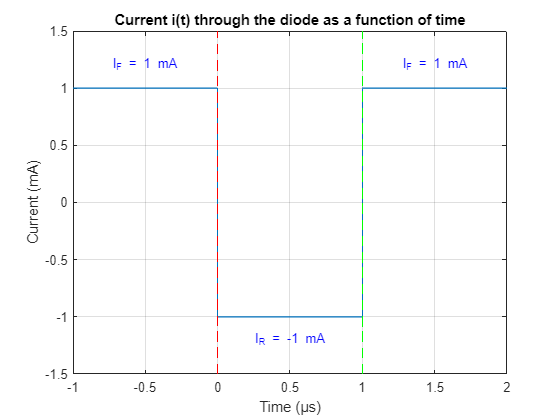

text(-0.5, 1.2, 'I_F = 1 mA', 'HorizontalAlignment', 'center', 'Color', 'blue');
text(0.5, -1.2, 'I_R = -1 mA', 'HorizontalAlignment', 'center', 'Color', 'blue');
text(1.5, 1.2, 'I_F = 1 mA', 'HorizontalAlignment', 'center', 'Color', 'blue');